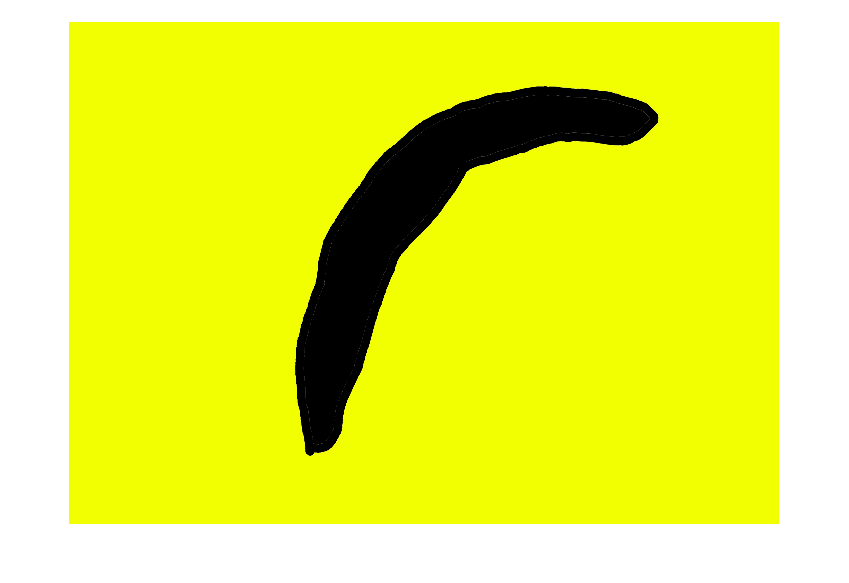

I=imread("image2.jpg");
imshow(I);

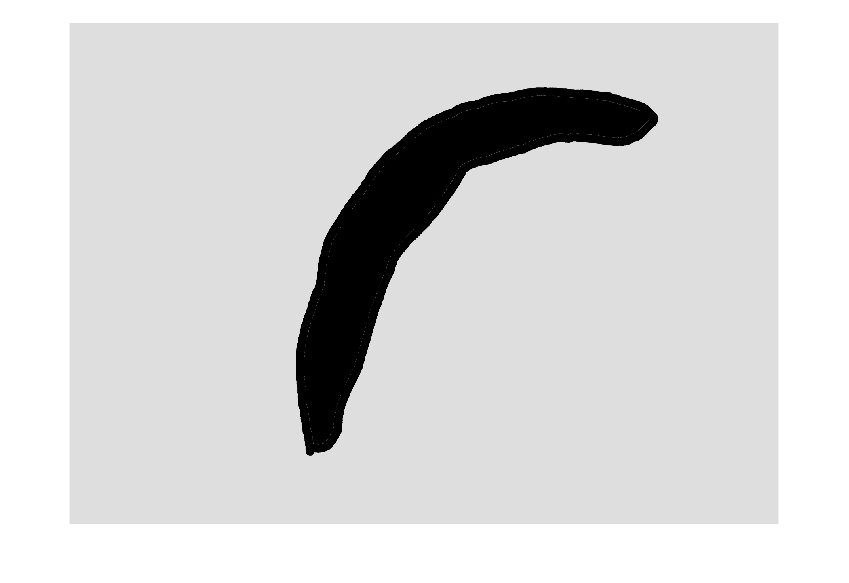

I=rgb2gray(I);
imshow(I);

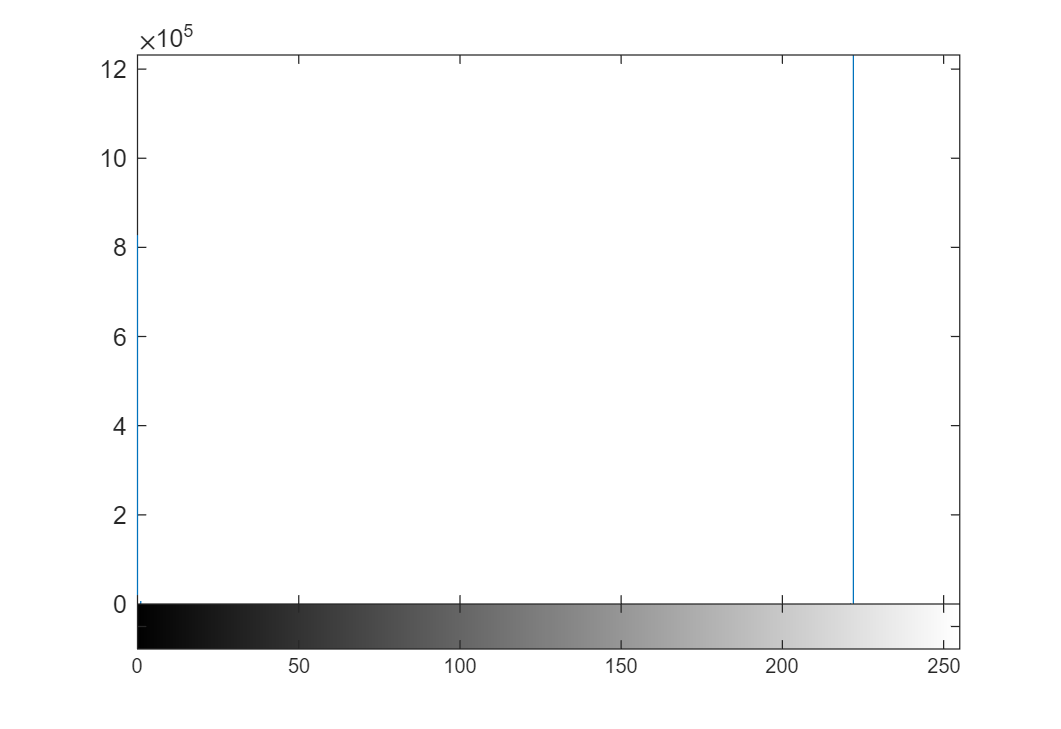

imhist(I);

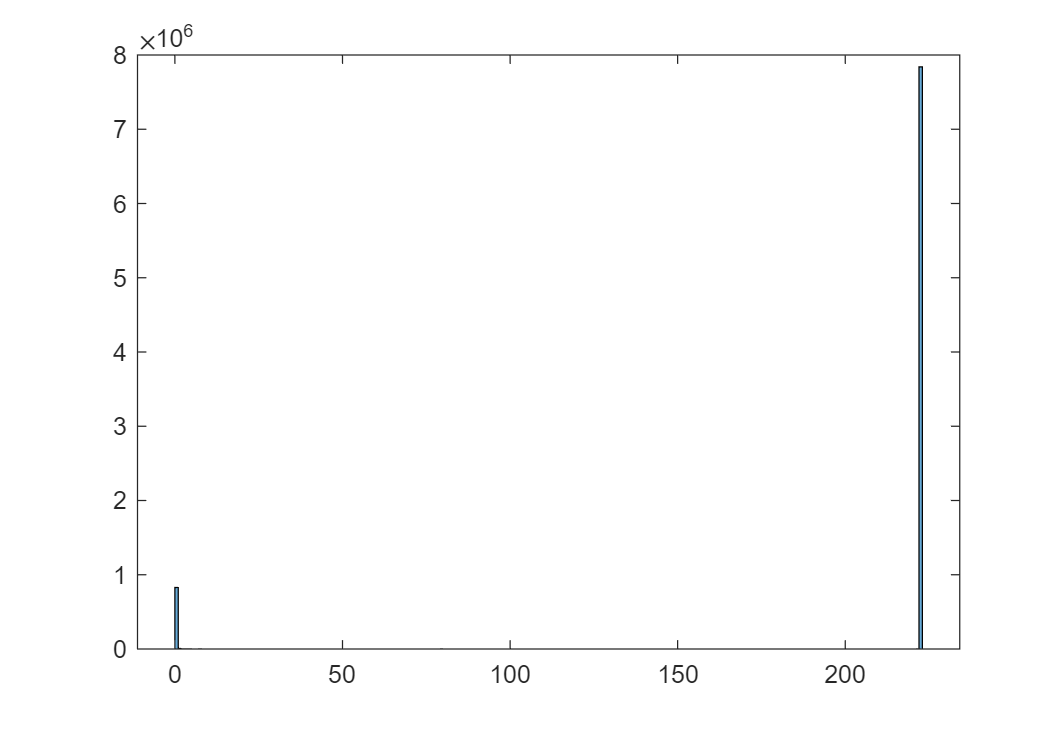

histogram(I)

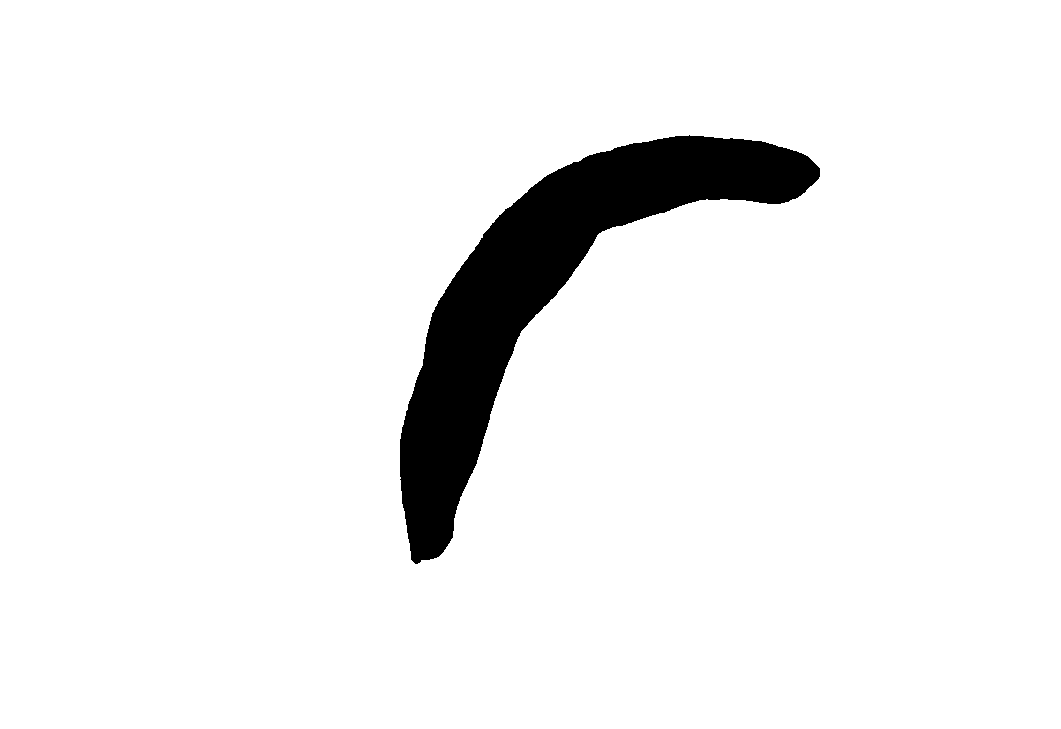

I=imbinarize(I,0.5);
imshow(I);

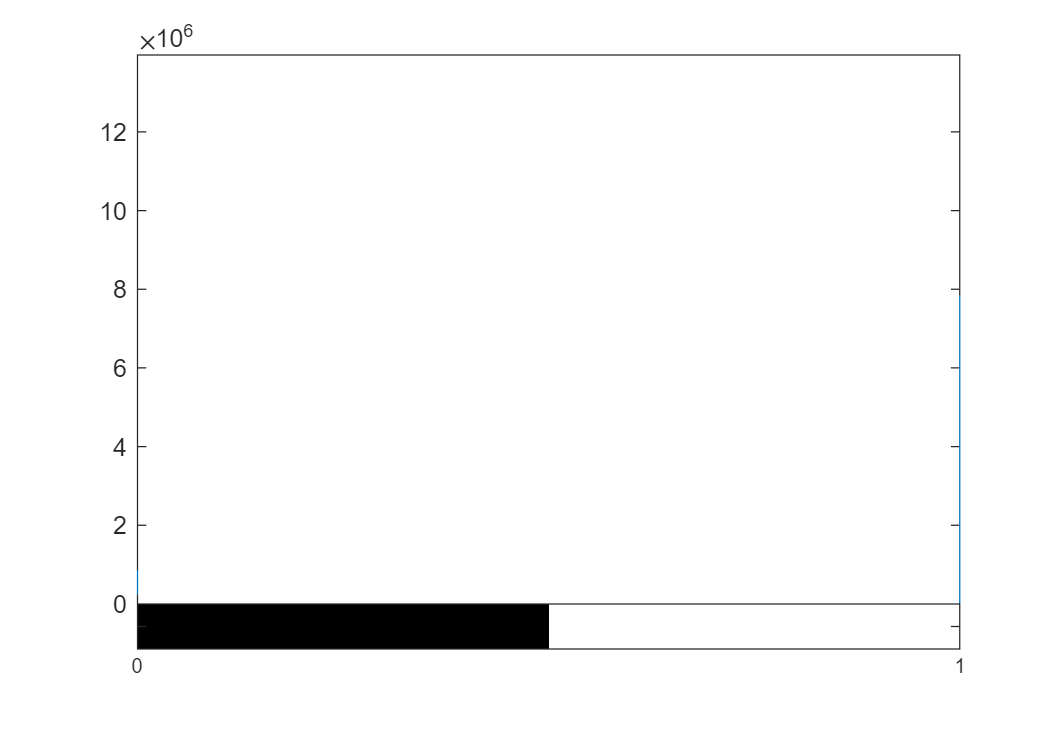

imhist(I);


feats=regionprops(I);

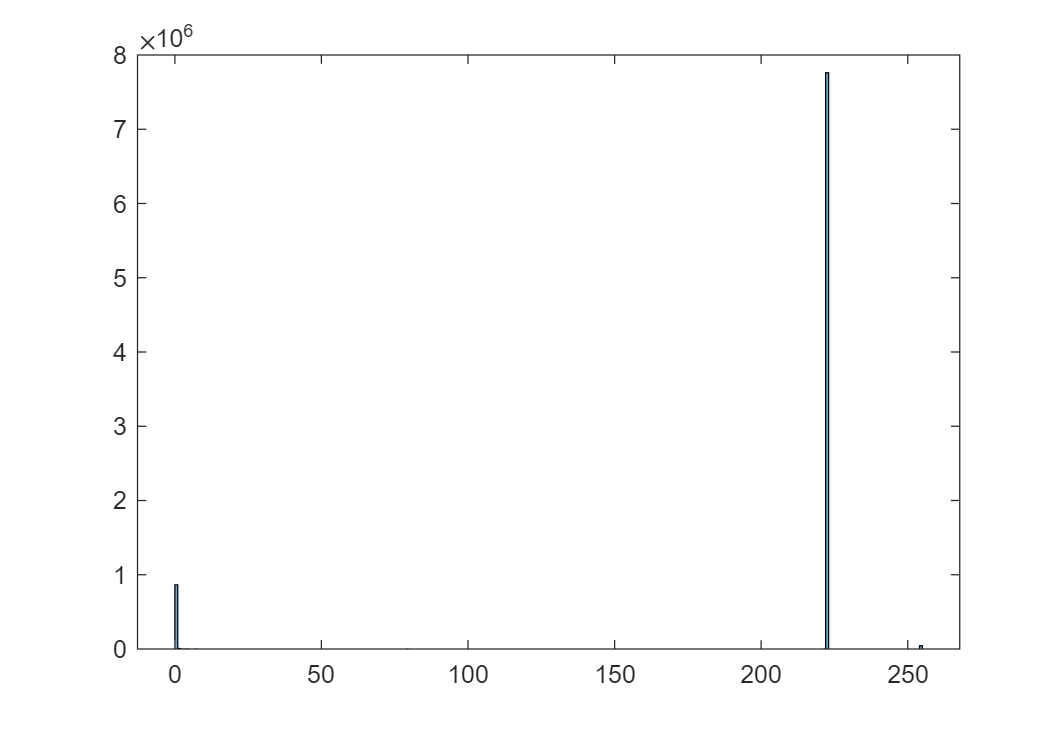

I=imread("image2.jpg");
I=rgb2gray(I);
I=imnoise(I,"salt & pepper",0.01);
histogram(I)

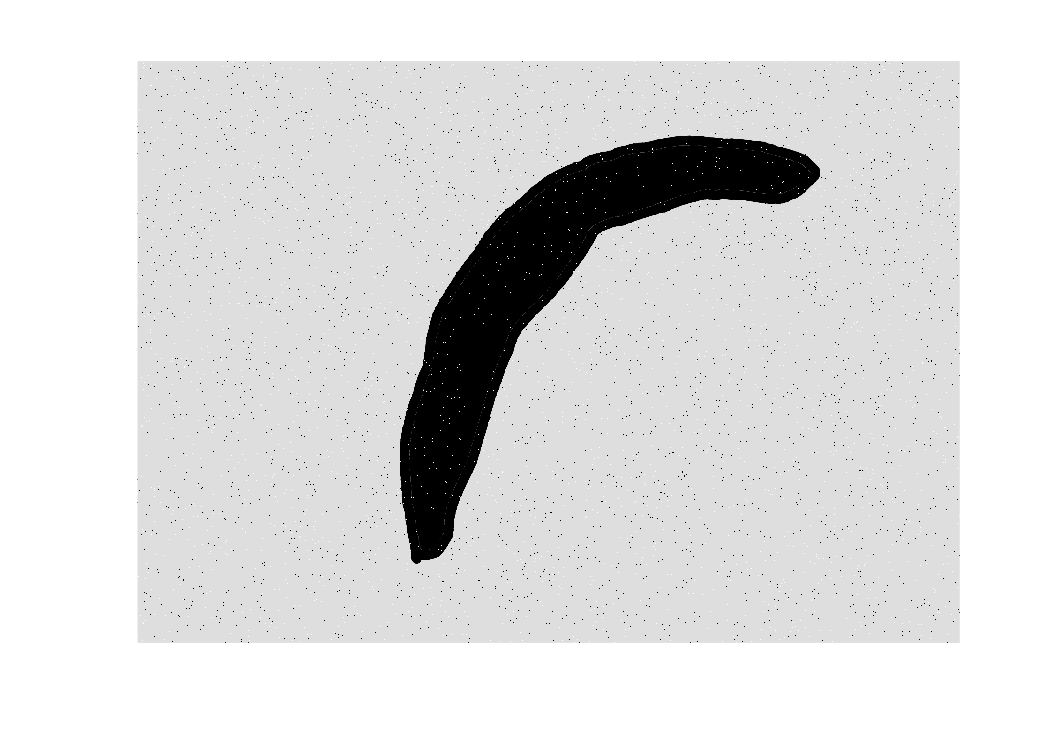

imshow(I);

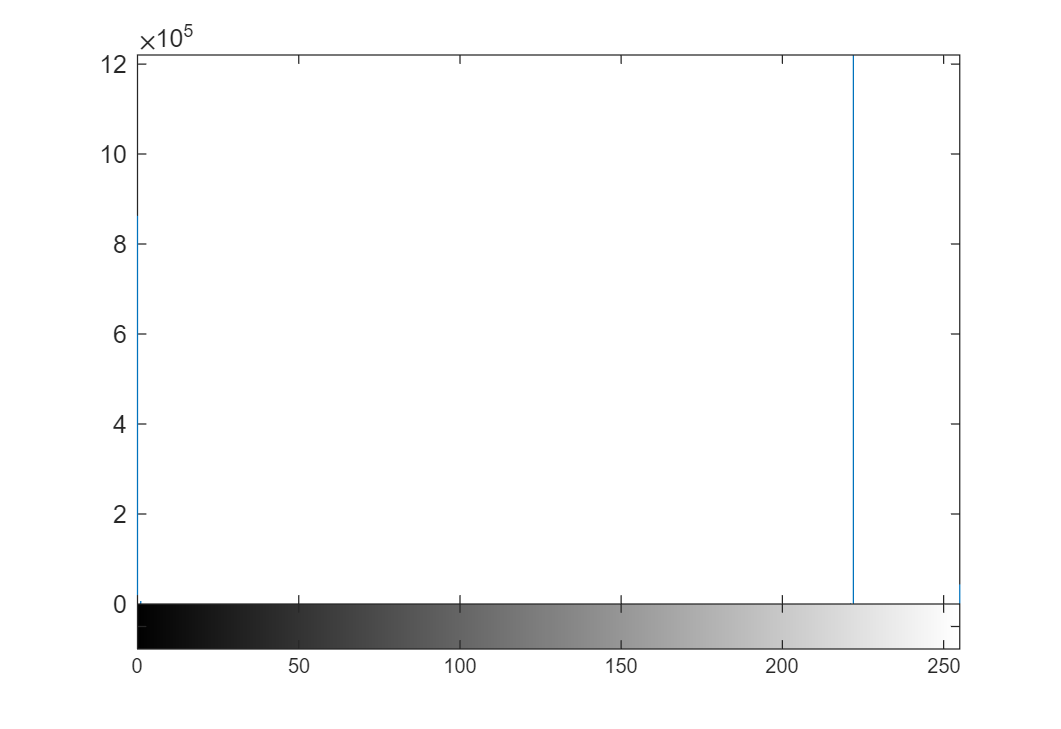

imhist(I);

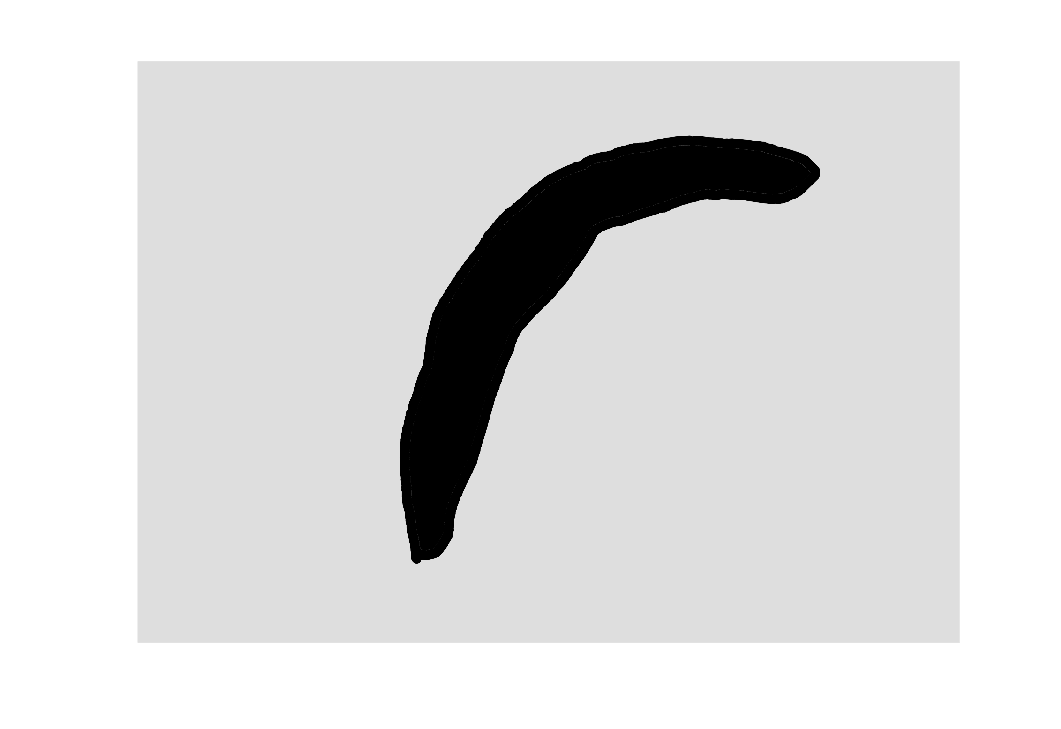


I = medfilt2(I,"symmetric");
imshow(I);

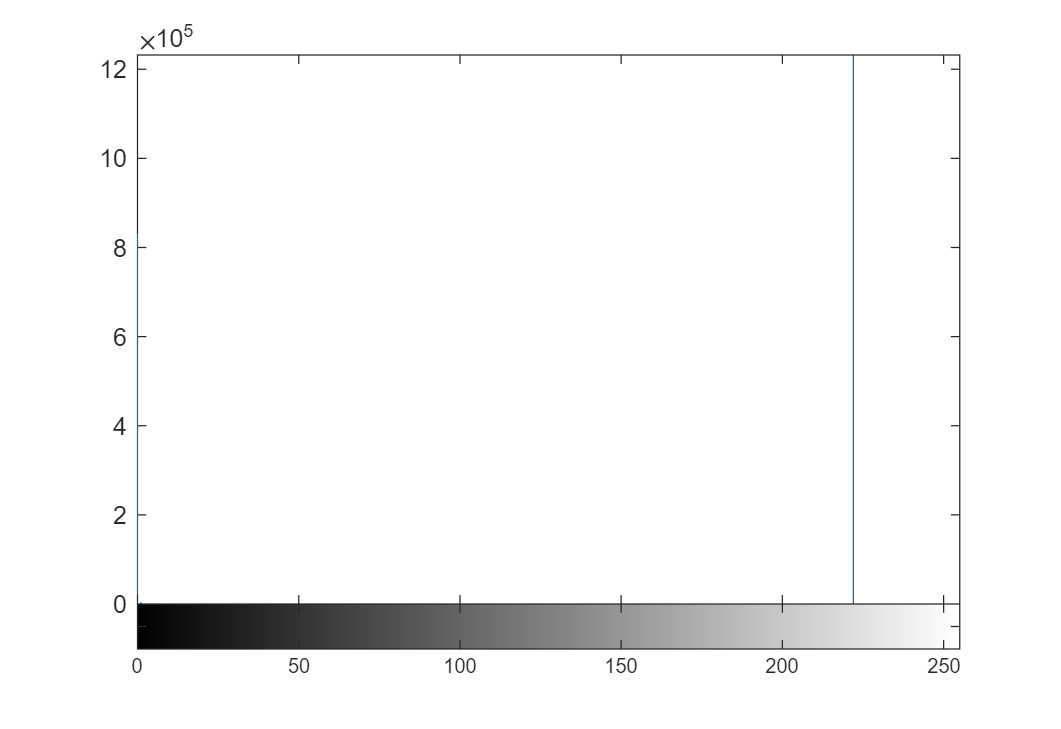

imhist(I);

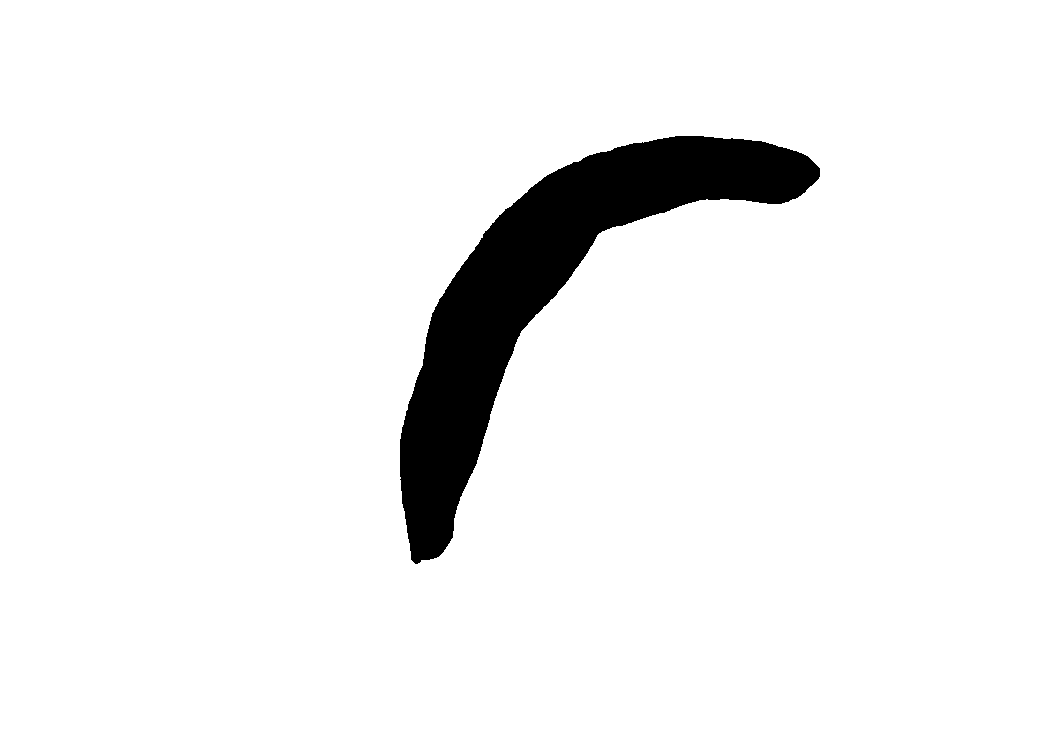



I=imbinarize(I,0.5);
imshow(I);

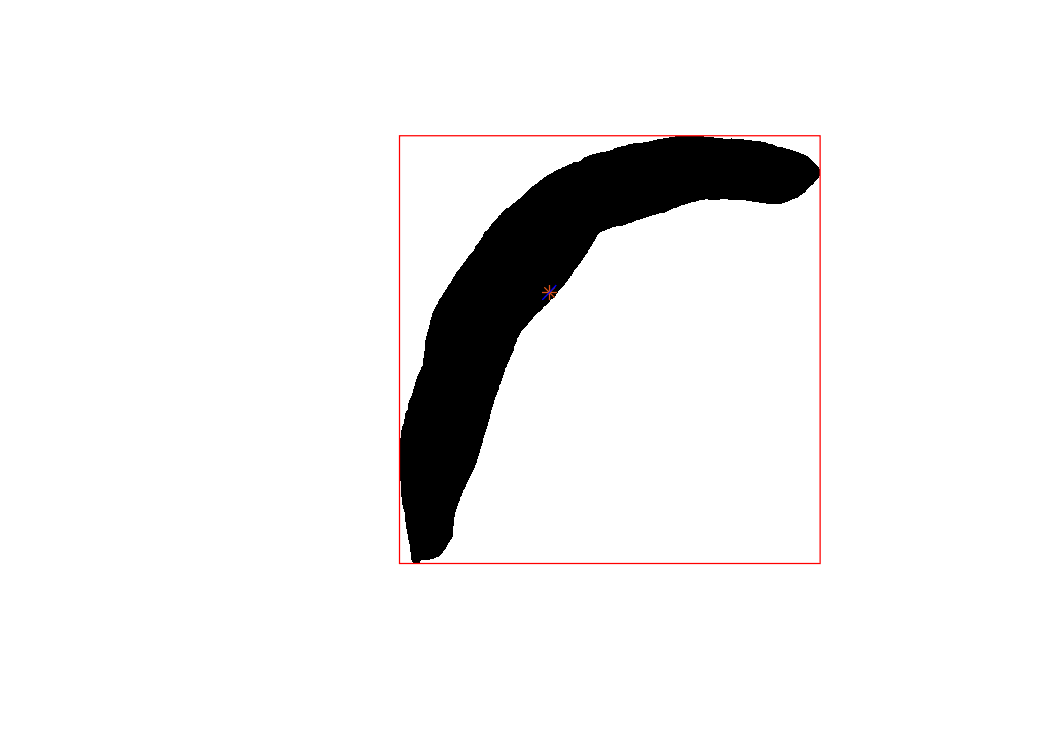


I=imerode(I,[0 1]);
imshow(I);hold on

I=1-logical(I);
feats=regionprops(I,'all');

rectangle('Position',feats.BoundingBox,'EdgeColor','red');
centroids =cat(1,feats.Centroid);
plot(centroids(:,1),centroids(:,2),'b*')

x=feats.Centroid(1,1);
y=feats.Centroid(1,2);
plot(x,y,"*");
a1=tan((feats.Orientation)*pi/180);
b1=y-a1*x;
x1=x-30;
x2=x+30;
y1=a1*x1+b1;
y2=a1*x2+b1;
plot([x1 x2],[y2 y1],'-b')
hold off

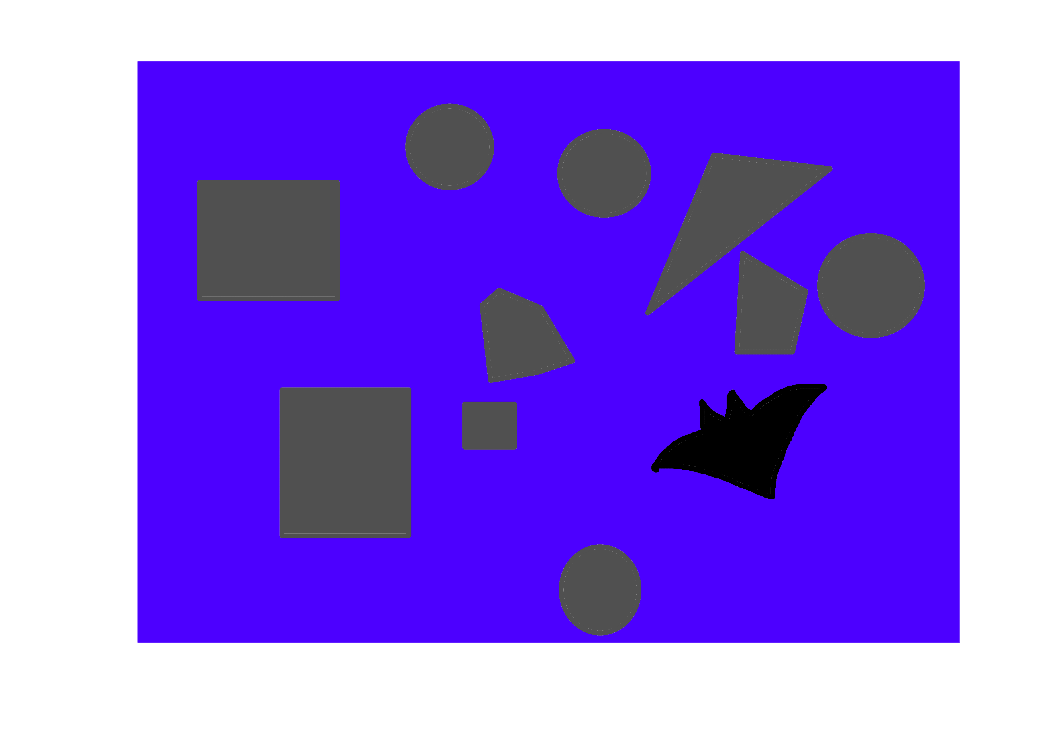

I=imread("image.jpg");
imshow(I);

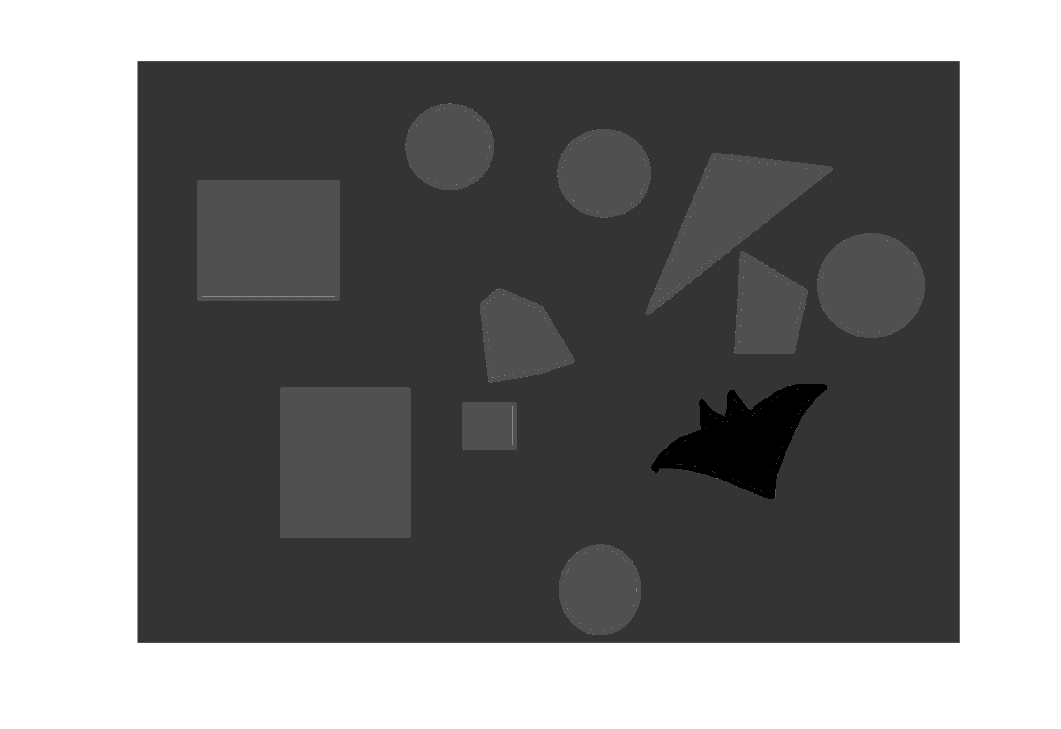

I=rgb2gray(I);
imshow(I);

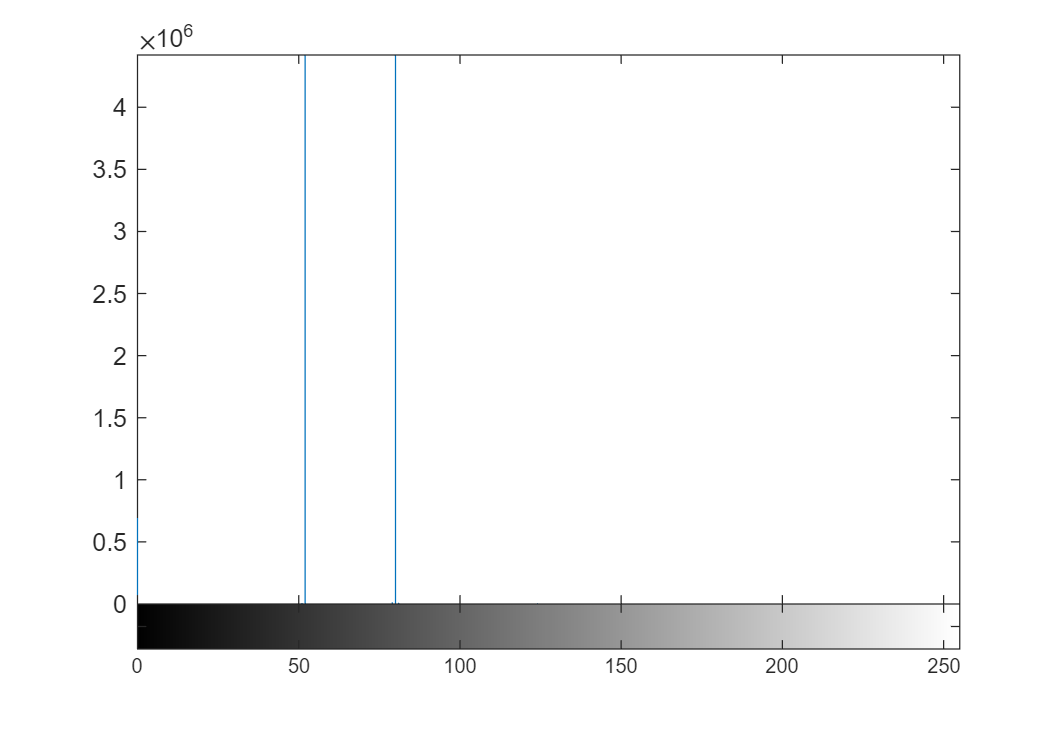

imhist(I);

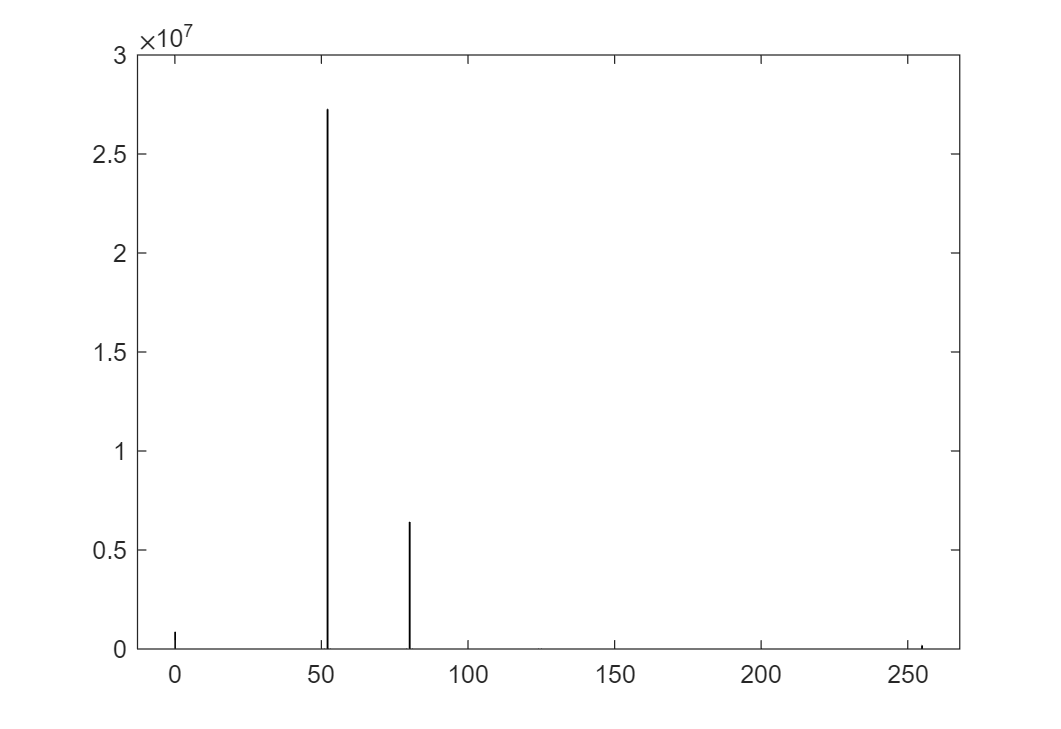


I=imnoise(I,"salt & pepper",0.01);
histogram(I)

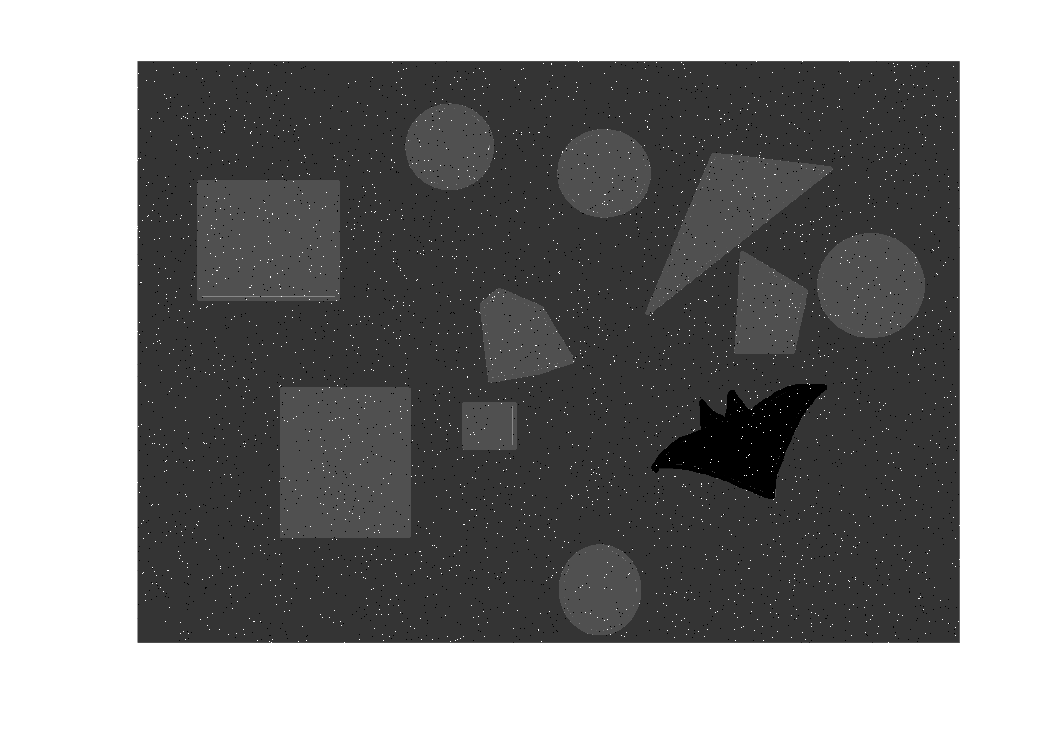

imshow(I);

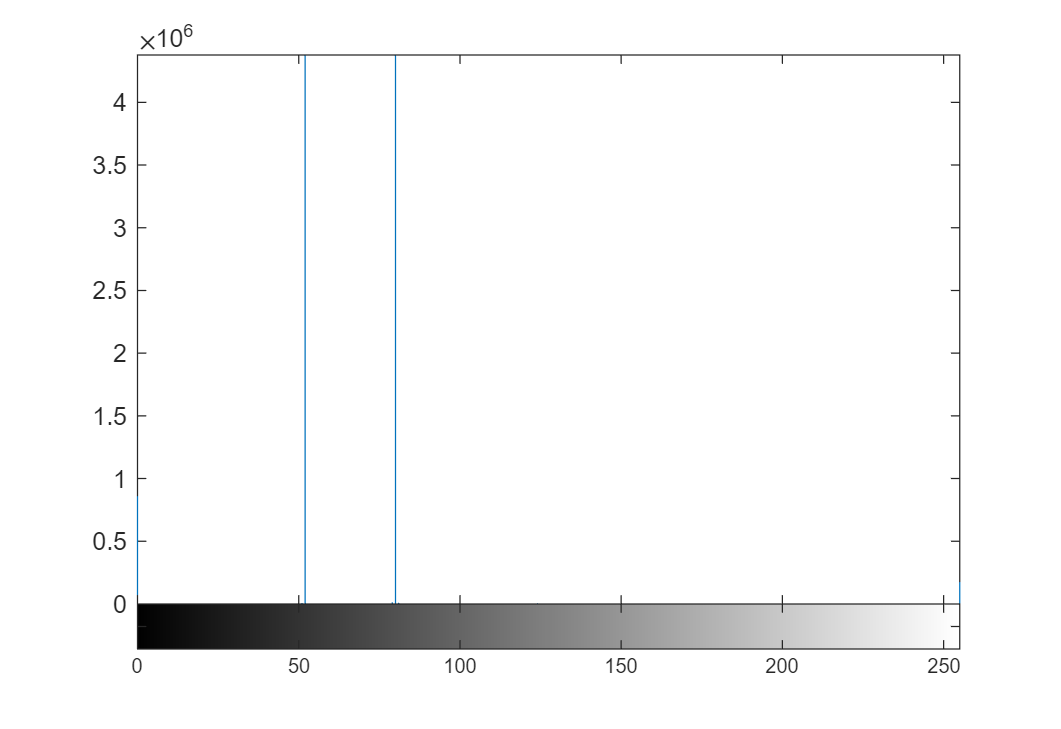

imhist(I);

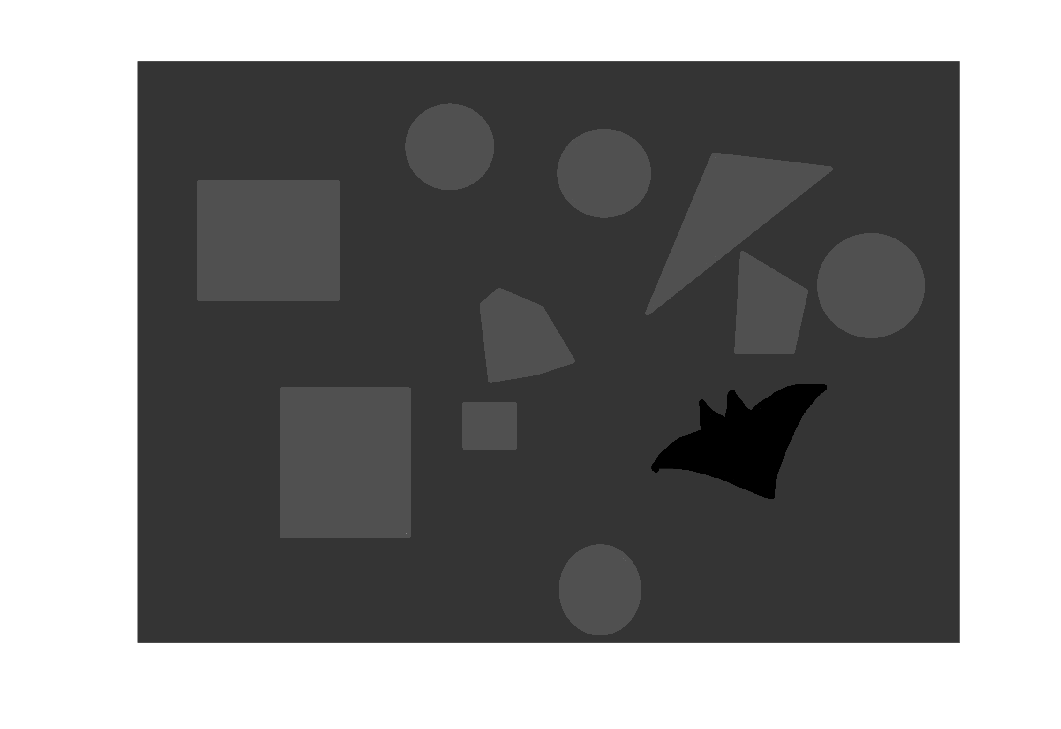


I = medfilt2(I,"symmetric");
imshow(I);

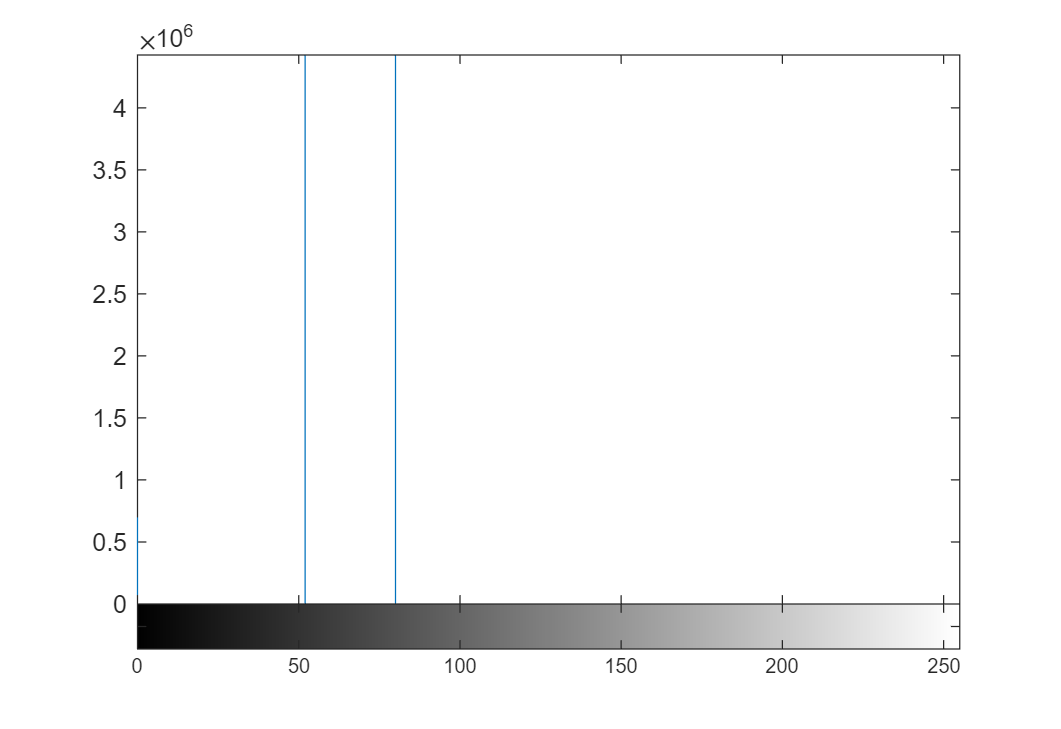

imhist(I);

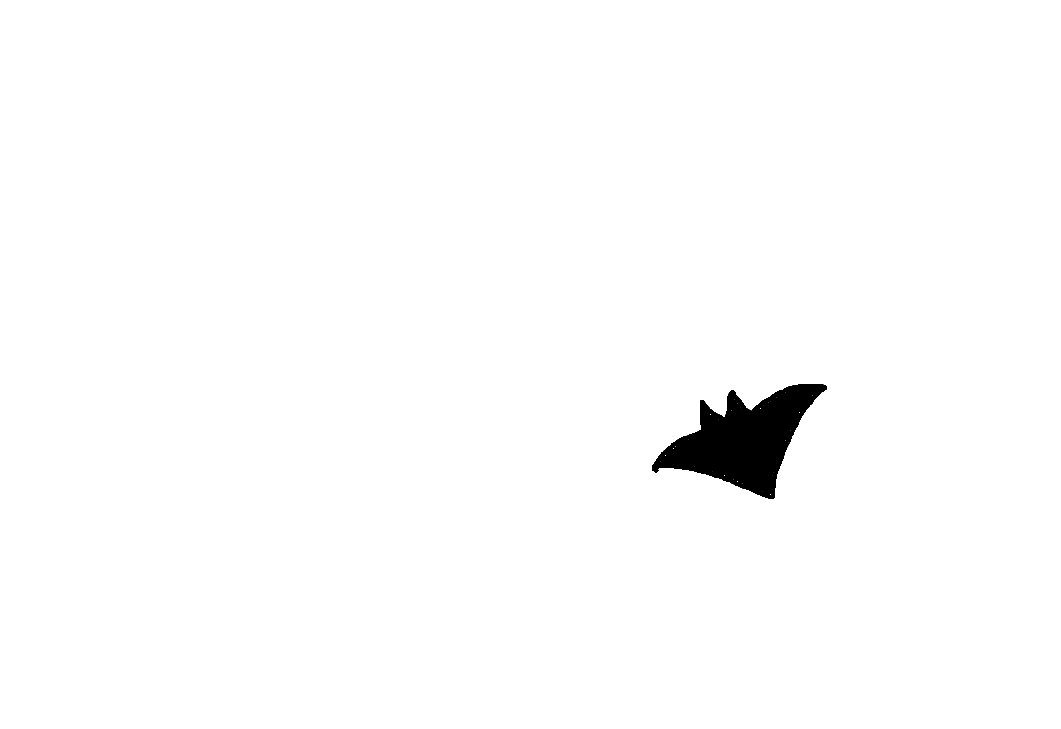


fil1=1/16*[1 2 1;2 4 2;1 2 1];
I=conv2(I,fil1);
imshow(I);

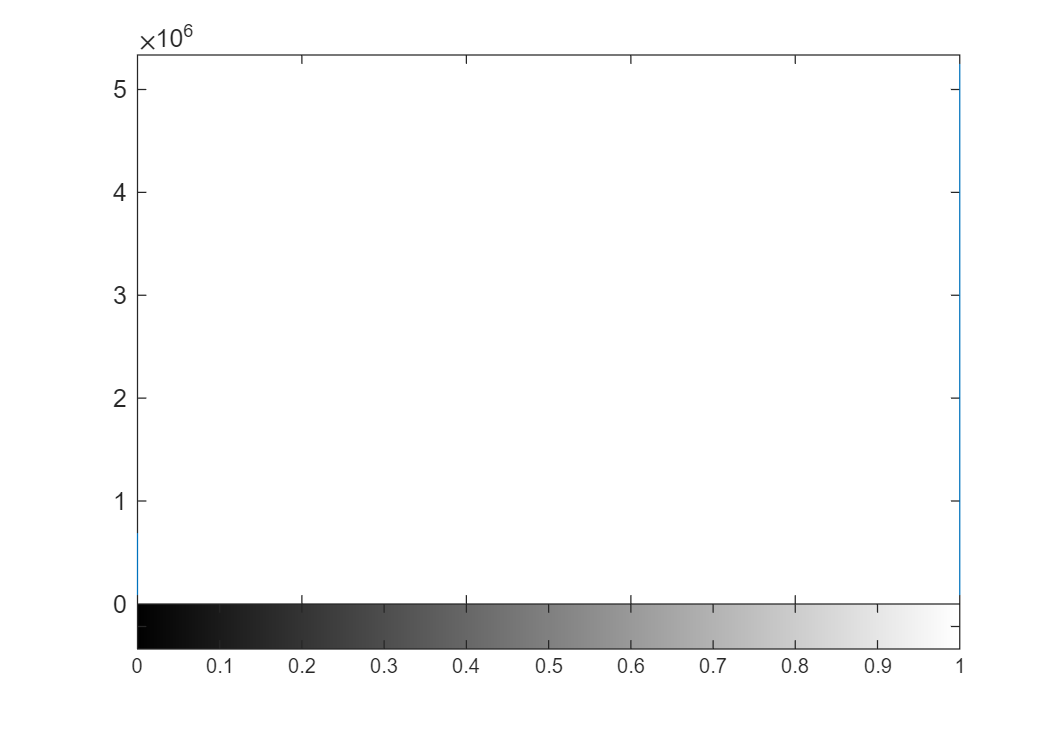

imhist(I);

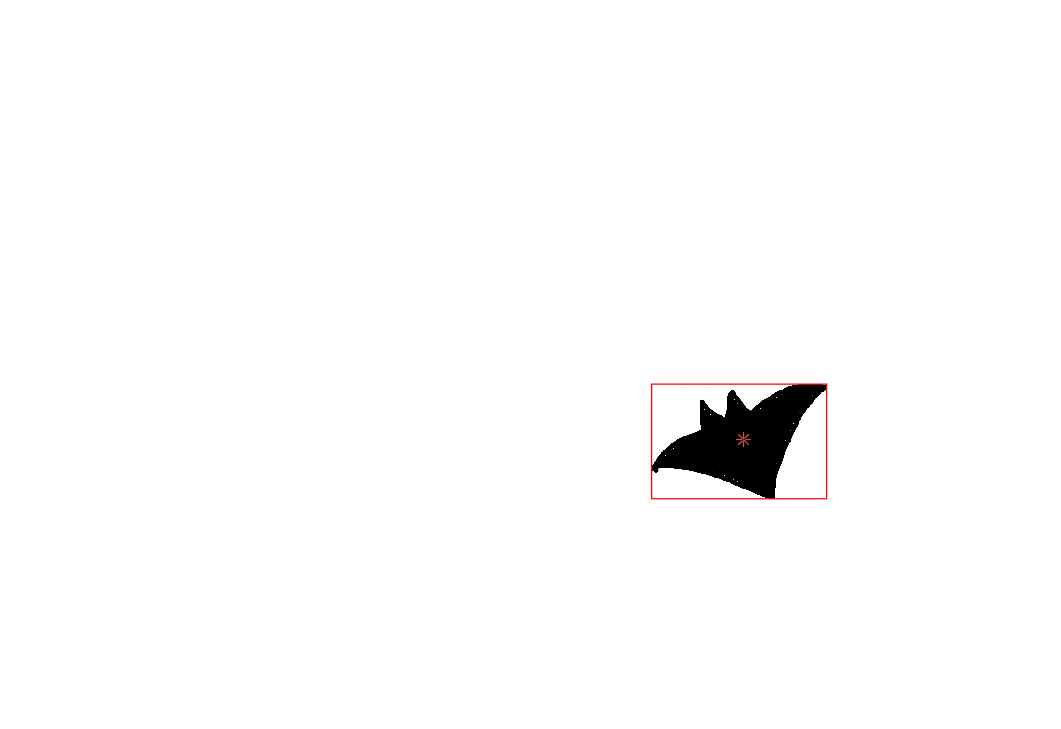


I=imerode(I,[0 1]);
imshow(I);hold on

I=1-logical(I);
feats=regionprops(I,'all');

rectangle('Position',feats.BoundingBox,'EdgeColor','red');
centroids =cat(1,feats.Centroid);
plot(centroids(:,1),centroids(:,2),'b*');

x=feats.Centroid(1,1);
y=feats.Centroid(1,2);

plot(x,y,"*");
a1=tan((feats.Orientation)*pi/180);
b1=y-a1*x;
x1=x-30;
x2=x+30;
y1=a1*x1+b1;
y2=a1*x2+b1;
plot([x1 x2],[y2 y1],'-b')
hold off

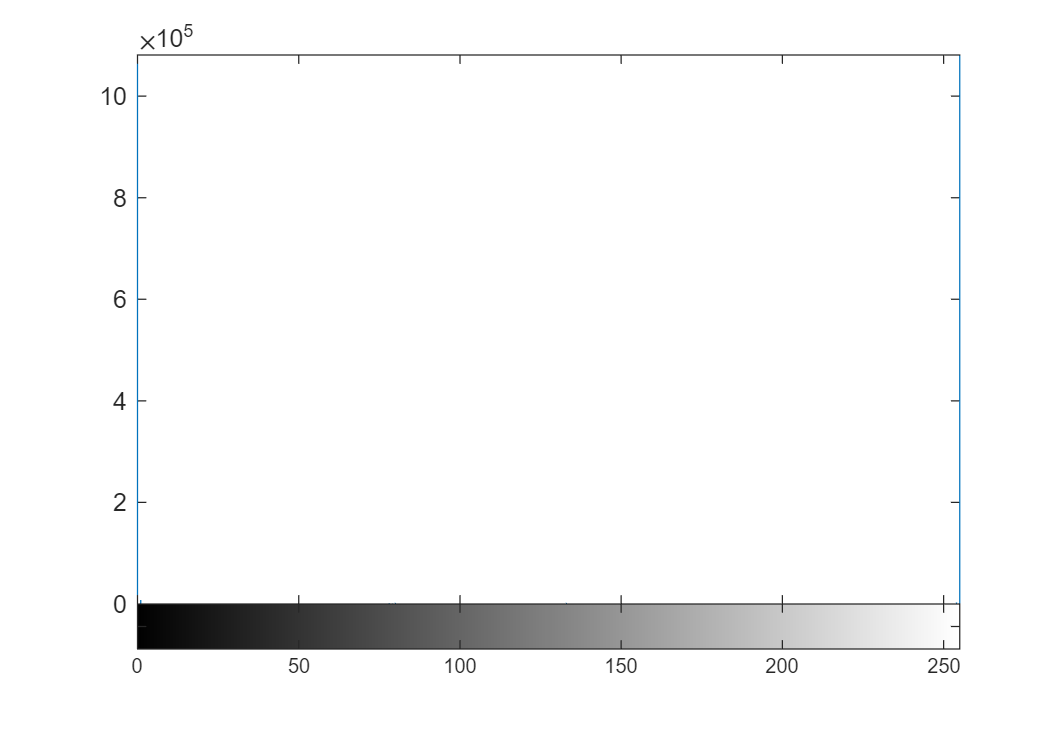

I=imread("image3.jpg");
I=rgb2gray(I);
imhist(I);

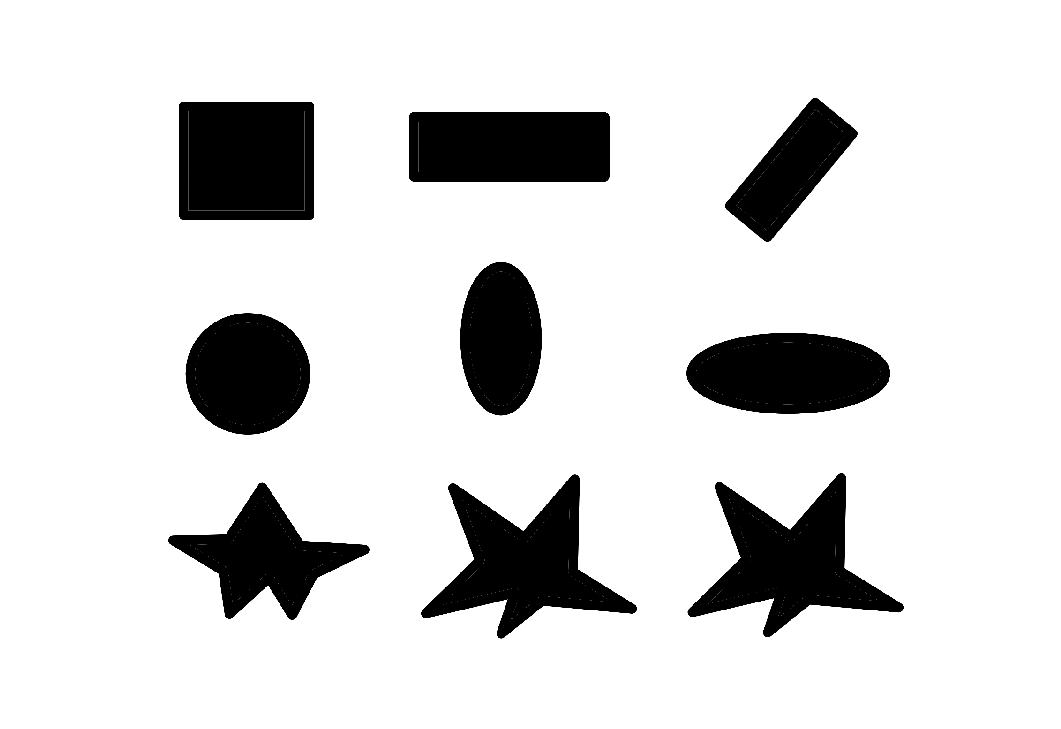

imshow(I);

% I = medfilt2(I,"symmetric");
imshow(I);

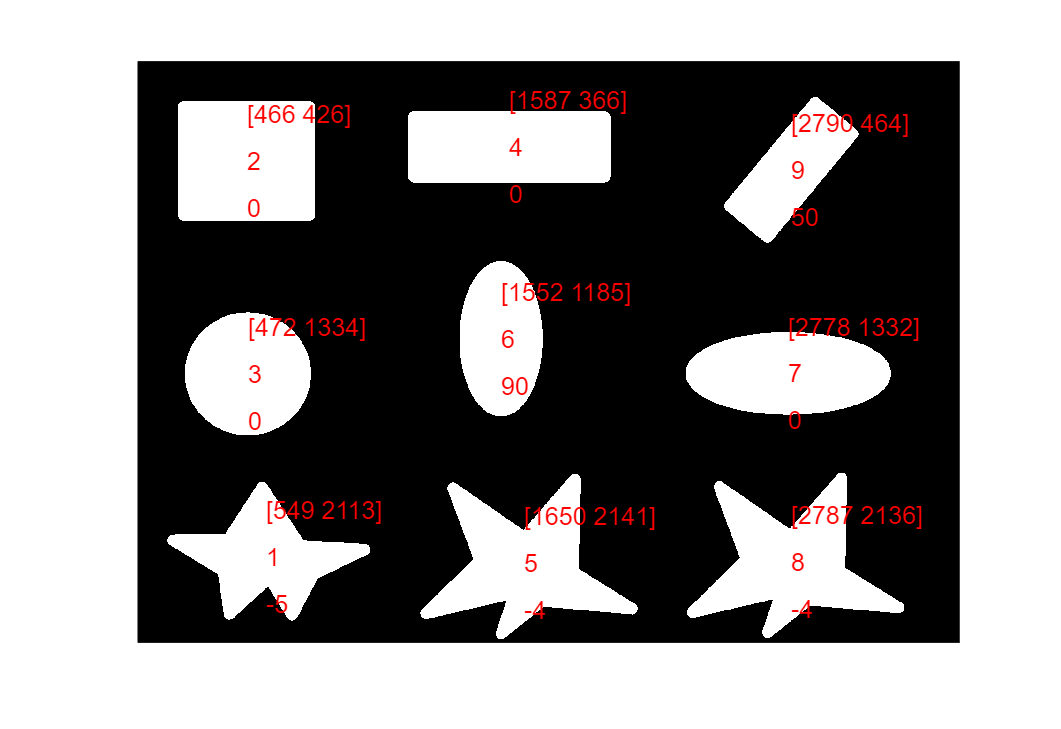

% I=imerode(I,[0 1]);
h = fspecial('disk', 5);
I = imfilter(I,h,'replicate');
I=(uint8(I));
I=1-im2bw(I,0.9);
imshow(I);hold on
[label, num]=bwlabel(I);
feats=regionprops(label,'Area','Centroid','BoundingBox','Orientation','Perimeter');hold off

for i=1:num
    text(feats(i).Centroid(1),feats(i).Centroid(2)+200,mat2str(round(feats(i).Orientation)),'Color','r')
    text(feats(i).Centroid(1),feats(i).Centroid(2)-200,mat2str(round(feats(i).Centroid)),'Color','r')
    text(feats(i).Centroid(1),feats(i).Centroid(2),mat2str(i),'Color','r')
end